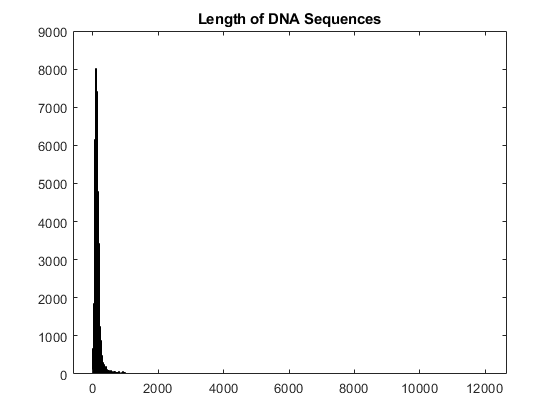

Data = fastaread('DNASequences.fasta'); %data input as structure array with 2 dimensions
DNA = struct2cell(rmfield(Data,'Header'));
%rmfield extracts header field leaving only the dna sequences
%struct2cell converts structure array into cell array of characters

length = [];
for i = 1:58286
    length(i) = strlength(DNA{i}); %find length of each character array
end

histogram(length)
title('Length of DNA Sequences')

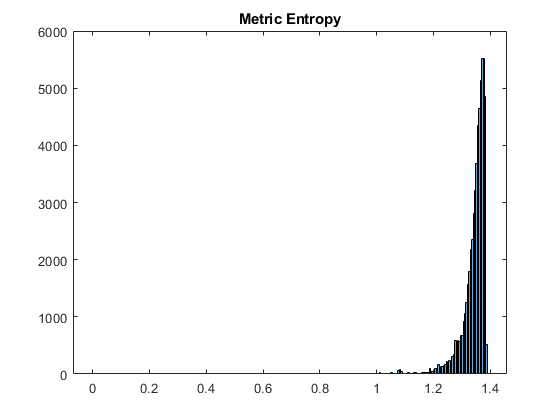

mEntropy = [];
for i = 1:58286
    mEntropy(i) = MetricEntropy(DNA{i},length(i));
    %calculate metric entropy for each DNA sequence
    %length corresponds to each DNA sequence
end

histogram(mEntropy)
title('Metric Entropy')

subsetMEntropy = mEntropy < 1.2; %create a logical array where this is true
%1 means the inequality is true, 0 means it is false
%find seqnences with metric entropy less than 1.2 (bottom 1.43%)
subsetDNA1 = {}; %empty character array to hold such sequences
counter = 1;
for i = 1:58286
    if subsetMEntropy(i) == 1 %whenever this is true
        subsetDNA1{counter} = DNA{i}; %take that value and put it into the new vector
        counter = counter + 1;
    end
end

save ('subsetDNA1.mat', 'subsetDNA1') %save to a .mat file

ans = 'subsetDNA1'

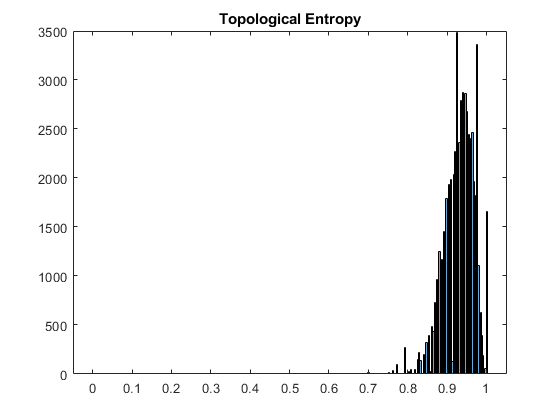

tEntropy = [];
for i = 1:58286
    tEntropy(i) = TopologicalEntropy(DNA{i});
    %calculate topological entropy for each DNA sequence
end

histogram(tEntropy)
title('Topological Entropy')

subsetTEntropy = tEntropy < 0.75;
%create a logical array where this is true
%1 means the inequality is true, 0 means it is false
%find seqnences with topological entropy less than 0.75 (bottom 1.44%)
subsetDNA2 = {}; %empty character array to hold such sequences
counter = 1;
for i = 1:58286
    if subsetTEntropy(i) == 1 %whenever this is true
        subsetDNA2{counter} = DNA{i}; %take that value and put it into the new vector
        counter = counter + 1;
    end
end

save('subsetDNA2.mat', 'subsetDNA2') %save to a .mat file